% Parametri Iniziali
num_pos = 8;
num_acq_totali = 25;
num_train = 20;
num_test = 5;

% Strutture per raccogliere le feature (le curve intere) e le etichette
% Le variabili assumono che il vettore frequenza sia lungo N punti
% Lo determiniamo caricando il primo file
primo_dato = load('Z_1_1.mat');
N_punti = length(primo_dato.misura_Ztrans.f_MHz);

% Preallocazione
Dati_Test = zeros(N_punti, num_test * num_pos);
Etichette_Vere = zeros(1, num_test * num_pos);
LUT = zeros(N_punti, num_pos); % Conterrà le 5 firme di riferimento

indice_test_globale = 1;

for x = 1:num_pos
    % Matrice temporanea per caricare le 25 acquisizioni della posizione x
    acquisizioni_x = zeros(N_punti, num_acq_totali);
    
    for y = 1:num_acq_totali
        nome_file = sprintf('Z_%d_%d.mat', x, y);
        try
            dati_caricati = load(nome_file);
            % Estraiamo il modulo di S12 
            acquisizioni_x(:, y) = abs(dati_caricati.misura_Ztrans.S_mean);
        catch
            warning('Errore nel caricamento %s. Verrà inserito NaN.', nome_file);
            acquisizioni_x(:, y) = NaN;
        end
    end
    
    % --- SPLIT RANDOMICO TRA TRAIN E TEST ---
    % Generazione di una permutazione casuale da 1 a 25
    indici_random = randperm(num_acq_totali);
    
    indici_train = indici_random(1:num_train);
    indici_test = indici_random(num_train+1:end);
    
    % Creazione del set di addestramento e costruzione della LUT
    dati_train = acquisizioni_x(:, indici_train);
    LUT(:, x) = mean(dati_train, 2, 'omitnan'); % La firma media per la posizione x
    
    % Salvataggio del set di validazione e delle relative etichette reali
    for i = 1:num_test
        Dati_Test(:, indice_test_globale) = acquisizioni_x(:, indici_test(i));
        Etichette_Vere(indice_test_globale) = x;
        indice_test_globale = indice_test_globale + 1;
    end
end

% --- FASE DI CLASSIFICAZIONE (TESTING) ---
% Vettore per salvare le etichette predette dal modello
Etichette_Predette = zeros(1, length(Etichette_Vere));

for i = 1:length(Etichette_Vere)
    curva_test = Dati_Test(:, i);
    
    % Vettore per memorizzare le distanze rispetto alle 5 firme della LUT
    distanze = zeros(1, num_pos);
    
    for k = 1:num_pos
        firma_LUT = LUT(:, k);
        % Calcolo della Distanza Euclidea (Root Mean Square Error)
        distanze(k) = sqrt(sum((curva_test - firma_LUT).^2, 'omitnan'));
    end
    
    % La classe predetta è quella corrispondente alla distanza minima
    [~, classe_predetta] = min(distanze);
    Etichette_Predette(i) = classe_predetta;
end

% --- VALUTAZIONE DELLE PERFORMANCE ---
% Calcolo dell'accuratezza globale
accuratezza = sum(Etichette_Vere == Etichette_Predette) / length(Etichette_Vere) * 100;
fprintf('Accuratezza del classificatore LUT: %.2f%%\n', accuratezza);

Accuratezza del classificatore LUT: 75.00%


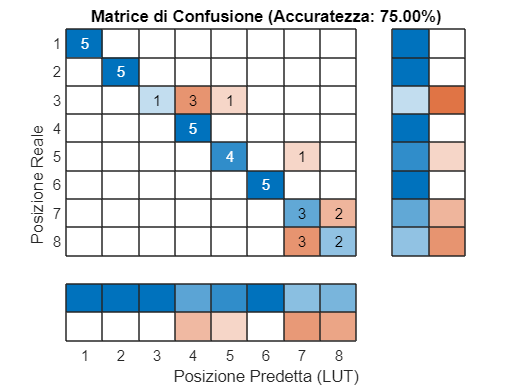


% Plot della Matrice di Confusione
figure('Name', 'Performance Classificatore LUT', 'Color', 'w');
cm = confusionchart(Etichette_Vere, Etichette_Predette);
cm.Title = sprintf('Matrice di Confusione (Accuratezza: %.2f%%)', accuratezza);
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.XLabel = 'Posizione Predetta (LUT)';


cm.YLabel = 'Posizione Reale';